# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r','J_r');

## Costanti del motore

Definizione delle costanti necessarie alla modellizzazione del comportamento del motore.

k_t = 0.1; % Costante di coppia [Nm/A]
R = 0.13; % Resistenza interna del motore[ohm]
L = 0.10e-3; % Induttanza del motore [H]
tau_e = L/R; % Costante di tempo elettrica [m]
tau = 0.1*22/26; % Rapporto di trasmissione
J_m_star = 3.7e-4+double(J_r)*tau^2; %Inerzia del motore ridotta all'albero [kg m^2]
fc=1000;
wc=2*pi*fc;
ti_i = tau_e;
kg_i = wc*tau_e*R; 
PI_I = kg_i*tf([ti_i,1],[ti_i,0])


PI_I =
 
  0.0004833 s + 0.6283
  --------------------
      0.0007692 s
 
Continuous-time transfer function.



## Modellizzazione del motore

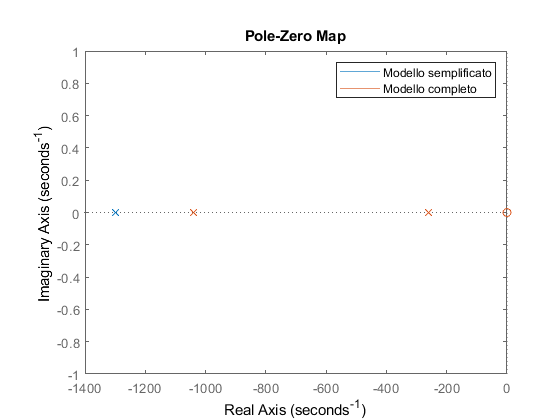

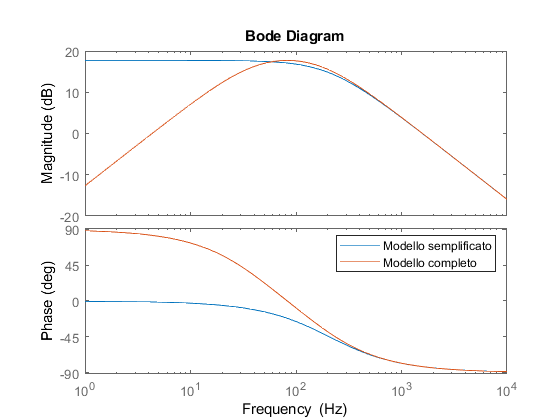

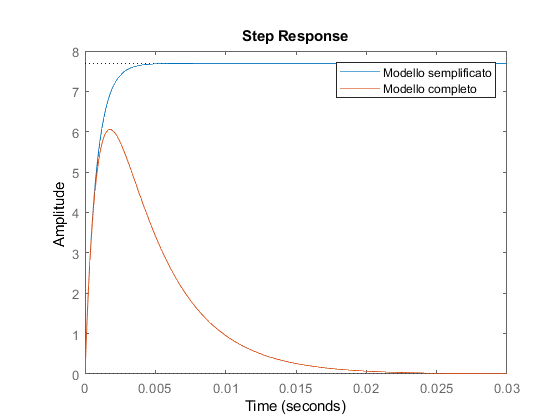

motor = struct with fields:
             name: 'Sinobi Serie 75 PX 053'
               Vn: 2050
               Wn: 870
               Cn: 3.6000
               In: 37
             Imax: 20
               Ra: 0.1300
               La: 1.0000e-04
                K: 0.1000
              tee: 0.0012
               Jm: 3.7000e-04
         J_m_star: 0.0014
                m: 8.1000
       radialLoad: 380
        axialLoad: 110
               te: 7.6923e-04
               tm: 0.0048
    tf_V_I_simple: [1×1 tf]
           tf_V_I: [1×1 tf]
           tf_V_w: [1×1 tf]


J_rotore = double(J_r) * tau^2;
motor = ConfigDCMotor(1, J_rotore)

K_gi = 0.6283


PI_I =
 
  0.0004833 s + 0.6283
  --------------------
      0.0007692 s
 
Continuous-time transfer function.



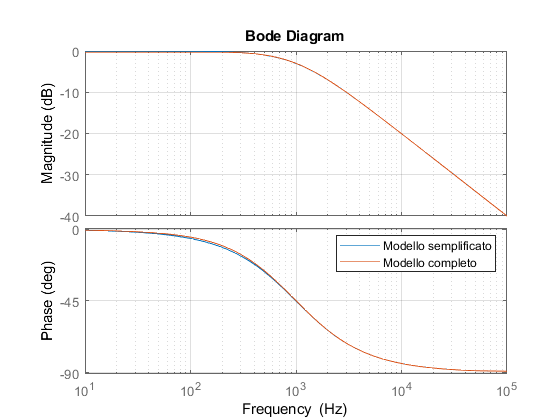

currentClosedLoop = struct with fields:
             f_c: 1000
             w_c: 6.2832e+03
             Kgi: 0.6283
    PI_regulator: [1×1 tf]
             H_I: [1×1 tf]
      H_I_simple: [1×1 tf]


currentClosedLoop = CurrentLoop(motor)

## Analisi stabilità in anello aperto

Studio dell'asintotica stabilità tramite gli autovalori della matrice A: come noto dalla teoria, il sistema è asintoticamente stabile se gli autovalori hanno tutti parte reale negativa; è instabile invece se è presente almeno un autovalore con parte reale strettamente positiva.

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

sys = ss(A_real,B_real,C_real,D_real) % Same of G


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -15.23       0
   x3       0       0       0       1
   x4       0       0   5.439       0
 
  B = 
            u1
   x1        0
   x2     2.75
   x3        0
   x4  -0.2612
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



sys_SISO = ss(A_real,B_real,[0,0,1,0],[0])


sys_SISO =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -15.23       0
   x3       0       0       0       1
   x4       0       0   5.439       0
 
  B = 
            u1
   x1        0
   x2     2.75
   x3        0
   x4  -0.2612
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



## Analisi grafiche

eig(A_real)

ans =          0
         0
    2.3322
   -2.3322


Come si vede il sistema non è asintoticamente per la presenza di autovalori con parte reale non strettamente positiva.

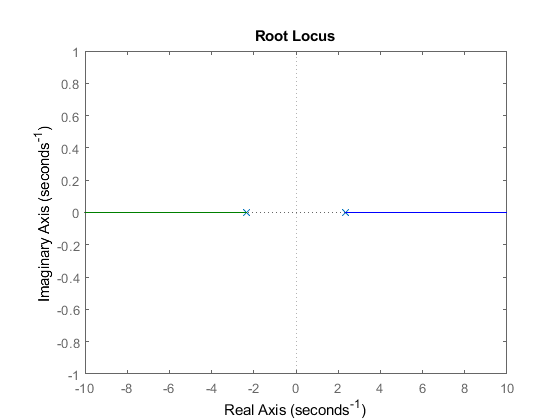

rlocus(sys_SISO)

Dal luogo delle radici si vede come sia impossibile, per il sistema ad anello aperto, andare a stabilizzare il polo che sta nel semipiano reale, variando il guadagno (questo a conferma di quanto detto in precedenza).

M_r = ctrb(sys_SISO) % Matrice di raggiungibilità

M_r =          0    2.7498         0    3.9776
    2.7498         0    3.9776         0
         0   -0.2612         0   -1.4207
   -0.2612         0   -1.4207         0


rank(M_r)

ans = 4

M_o = obsv(sys_SISO) % Matrice di osservabilità

M_o =          0         0    1.0000         0
         0         0         0    1.0000
         0         0    5.4392         0
         0         0         0    5.4392


rank(M_o)

ans = 2

Si vede come il sistema, in anello aperto, non sia asintoticamente stabile (come previsto), dalle analisi sugli autovalori e sui poli.

Lo stato del sistema, nel nostro caso, risulta essere accessibile, poichè sono misurazioni che possono essere direttamente realizzate per mezzo di tecniche di sensor fusion.

## Posizionamento poli

Per ora vogliamo controllare solamente l'angolo $\theta \;$, e quindi ci poniamo in una condizione di sistema SISO (input la coppia motrice, output l'accelerazione $\ddot{\theta \;}$):


$${\left\{\begin{array}{c}
x\left(t\right)=Ax{\left(t\right)}+Bu\left(t\right)\\
y{\left(t\right)}=Cx{\left(t\right)}+Du\left(t\right)
\end{array}\right)}$$


Utilizzando la legge di controllo, basata su uno ***state feedback controller, ***è:


$$u{\left(t\right)}=-Kx{\left(t\right)}+w{\left(t\right)}$$


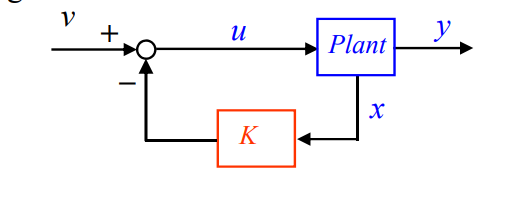

Per la scelta della matrice K


$$x{\left(t\right)}=Ax{\left(t\right)}+Bu{\left(t\right)}=Ax{\left(t\right)}+B{\left(-Kx{\left(t\right)}+w{\left(t\right)}\right)}\to legge\ di\ controllo\ in\ anello\ chiuso$$



$$=Ax{\left(t\right)}-BKx{\left(t\right)}+Bw\left(t\right)={\left(A-BK\right)}x{\left(t\right)}+Bw{\left(t\right)}$$



$$A_{cl} =A-BK=matrice\;di\;stato\;in\;closed-loop$$


Per andare a calcolare questo vettore dei poli K, possiamo utilizzare il comando ***place***.

Per fare ciò ci atteniamo ai parametri richiesti per entrambi i poli, ovvero:

- Smorzamento $=\xi =0\ldotp 7$

- Pulsazione naturale polo $=\omega {\;}_{n\;} =2\bullet \pi \bullet f_{\textrm{propria}}$

In generale sappiamo che


$$G{\left(S\right)}=\frac{\omega {\;}_n^{2\;} }{s^2 +2\xi \omega {\;}_n s+\omega {\;}_n^{2\;} }=\frac{1}{1+2∙\frac{\textrm{𝜉}}{{\textrm{𝜔}}_n }s+\frac{s^2 }{{\textrm{𝜔}}_n^2 }}$$


Per trovare i poli mi basta risolvere l'equazione al denominatore, trovando i valori di s che l'annullano:

syms xsi wn1 wn2 s;
% Definisco le funzioni di trasferimento
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0

$$dd\_1 = s^{2}+2\,\mathrm{xsi}\,s\,{\mathrm{wn}}_{1}+{{\mathrm{wn}}_{1}}^{2}=0$$

dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0

$$dd\_2 = s^{2}+2\,\mathrm{xsi}\,s\,{\mathrm{wn}}_{2}+{{\mathrm{wn}}_{2}}^{2}=0$$

sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

fn1 = 20; % [Hz]
 fn1 = 0.2; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

fn2 = 2; % [Hz]
 fn2 = 0.02; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1});
pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2});
pol_1_real = double(pol_1)

pol_1_real =   -0.8796 + 0.8974i
  -0.8796 - 0.8974i


pol_2_real = double(pol_2)

pol_2_real =   -0.0880 + 0.0897i
  -0.0880 - 0.0897i


K = place(A_real,B_real,[pol_1_real', pol_2_real'])

K =    -0.0023   -0.0278  -28.1397   -7.7022


save('K.mat','K');


Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_real - B_real * K;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl)

ans =   -0.8796 + 0.8974i
  -0.8796 - 0.8974i
  -0.0880 + 0.0897i
  -0.0880 - 0.0897i


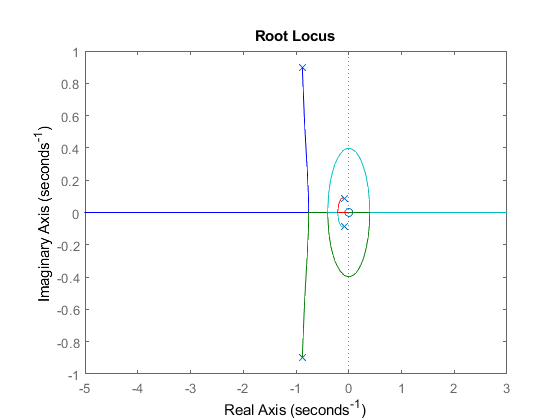

sys_cl = ss(A_cl,B_real,[0,0,1,0],[0]);
rlocus(sys_cl)

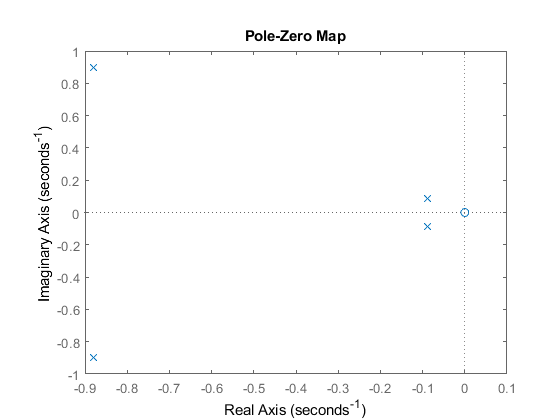

pzmap(sys_cl)

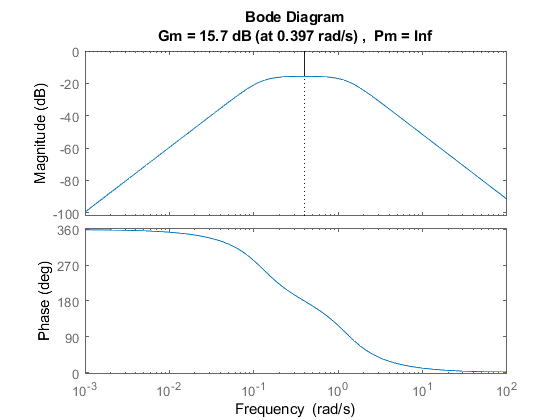

margin(sys_cl)

Si vede quindi come, soprattutto dal luogo delle radici, che abbiamo ottenuto la possibilità di andare a muovere i poli nel semipiano a parte reale negativa.

Posso utilizzare un'altra tecnica per realizzare il place dei poli (LQR - Regolatore Lineare Quadratico) che rappresenta una soluzione ottima per il pole placement:

Q = eye(4);
R = 1;
K_lqr = lqr(A_real,B_real,Q,R)

K_lqr =    -1.0000   -2.3459 -115.4689  -54.9525



A_cl_lqr = A_real - B_real * K_lqr;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl_lqr)

ans =   -3.3303 + 0.0000i
  -2.1436 + 0.0000i
  -1.2143 + 0.2519i
  -1.2143 - 0.2519i


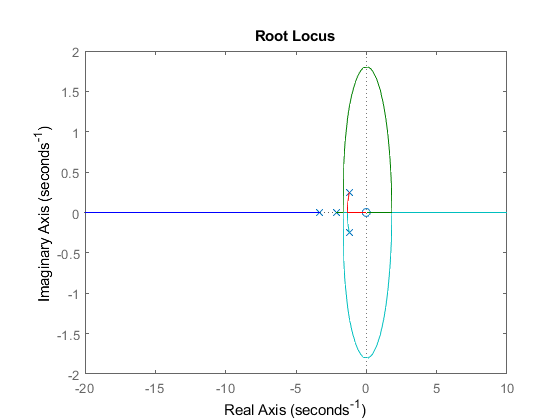

sys_cl_lqr = ss(A_cl_lqr,B_real,[0,0,1,0],[0]);
rlocus(sys_cl_lqr)

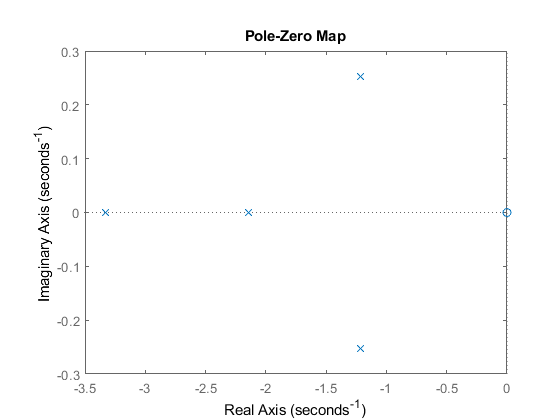

pzmap(sys_cl_lqr)

## Simulazione

### Condizioni iniziali

% Initial condition for open loop model
x_0 = [0; 0; 5 * pi / 180; 0];
phi_iniziale = x_0(1);
phi_p_iniziale = x_0(2);
theta_iniziale = x_0(3);
theta_p_iniziale = x_0(4);
r_simulazione = double(r);
control_on = 0;
t_end = 5;
Ts = 1/100;
%vale solo nel non lineare alpha
alpha_simulazione = double(0);
k_simulazione = K;
disp('Open loop');

Open loop


## Sistema in anello aperto

### Sistema Lineare

disp('Linear system');

Linear system


simOut = sim('VAB_Linear');

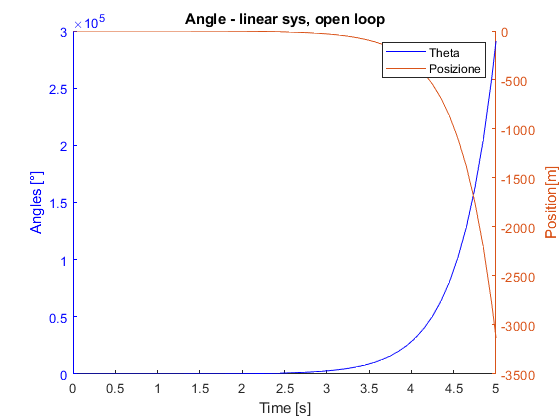

completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear sys, open loop')
hold off

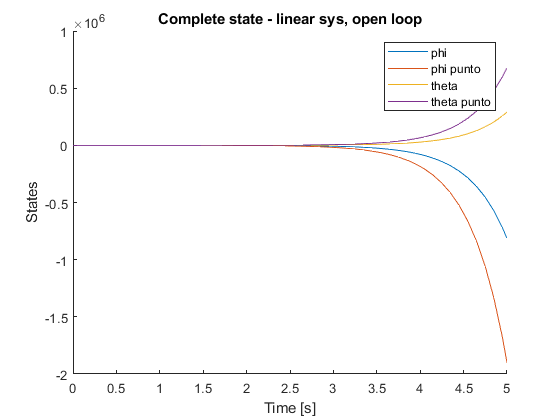



figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear sys, open loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off


% for i=1:size(completeState,1)
%     call_plot(completeState(i,:))
% end

### Sistema non lineare

disp('Non linear system');

Non linear system


simOut = sim('VAB_non_linear.slx');

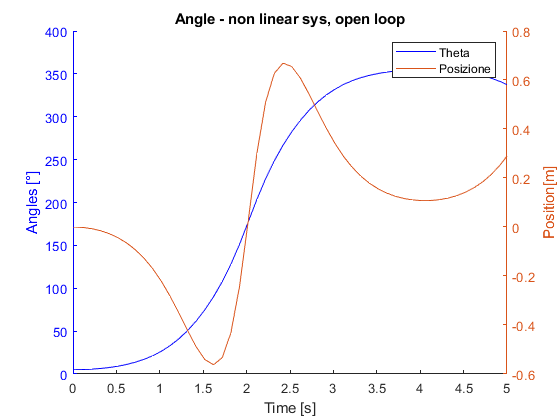

completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear sys, open loop')
hold off

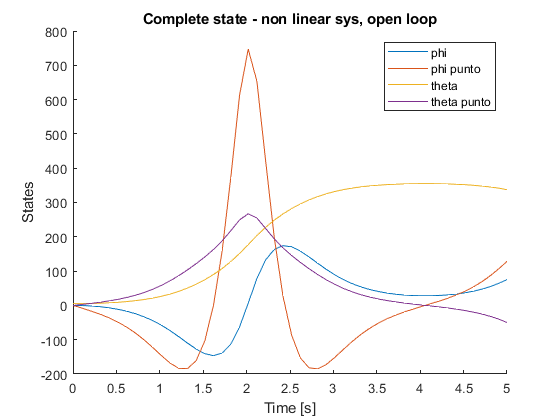


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear sys, open loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

## Simulazione con controllo

### Sistema lineare

disp('Closed loop');

Closed loop


disp('Linear system');

Linear system


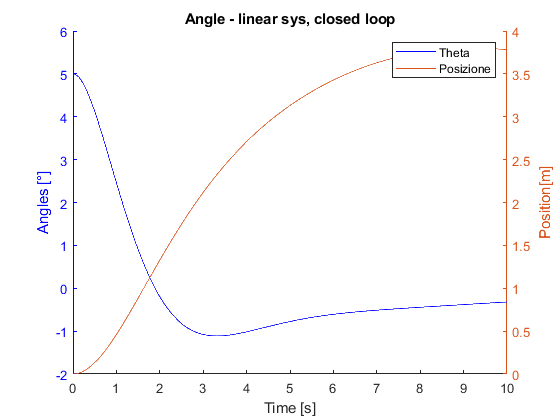

control_on = 1;
t_end = 10;
Ts = 1/100;

simOut = sim('VAB_Linear');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
actual_torque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear sys, closed loop')
hold off

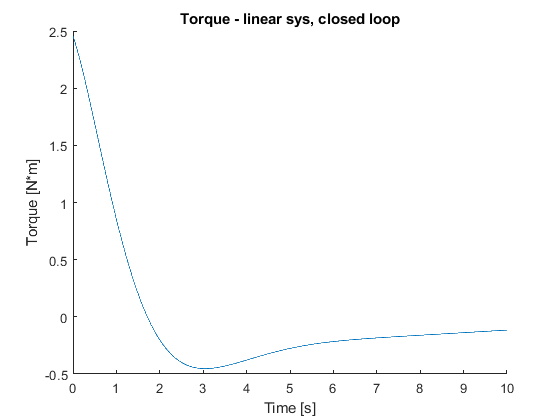


figure
hold on
plot(tout, [torque,actual_torque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - linear sys, closed loop')
hold off

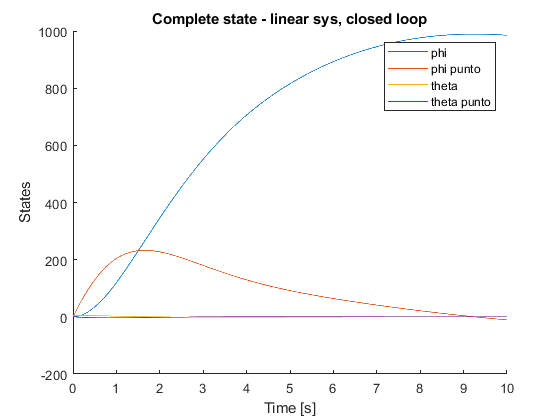


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

### Sistema non lineare

disp('Non linear system');

Non linear system


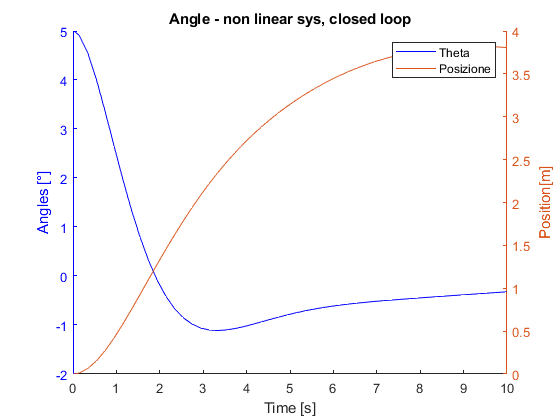

control_on = 1;
simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear sys, closed loop')

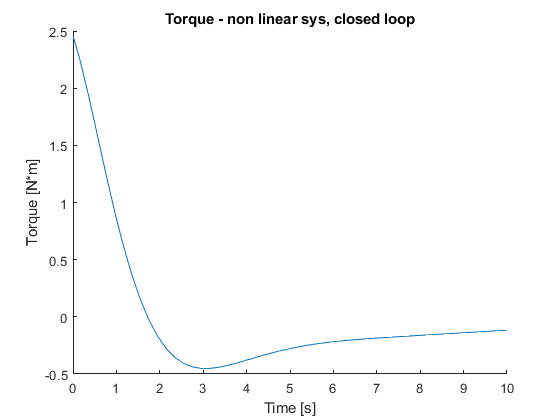

figure
hold on
plot(tout, torque)
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - non linear sys, closed loop')
hold off

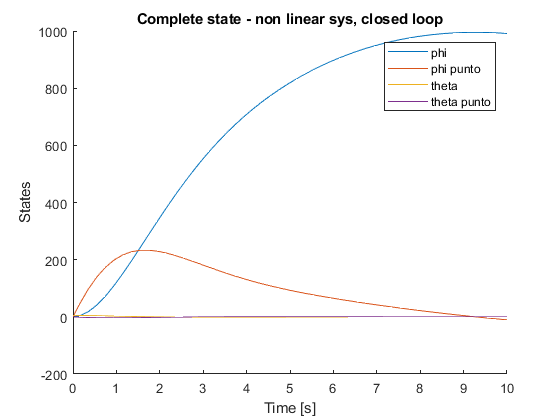


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

clearvars ax

NB: State needs to be defined in rad!

call_plot(completeState * pi / 180);

Error using matlab.graphics.axis.Axes/get
Operation terminated by user

Error in ylabel (line 56)
    h = get(ax,'YLabel');

Error in call_plot>PlotS2A (line 69)
ylabel('Y')

Error in 